# Single-antenna Basestation

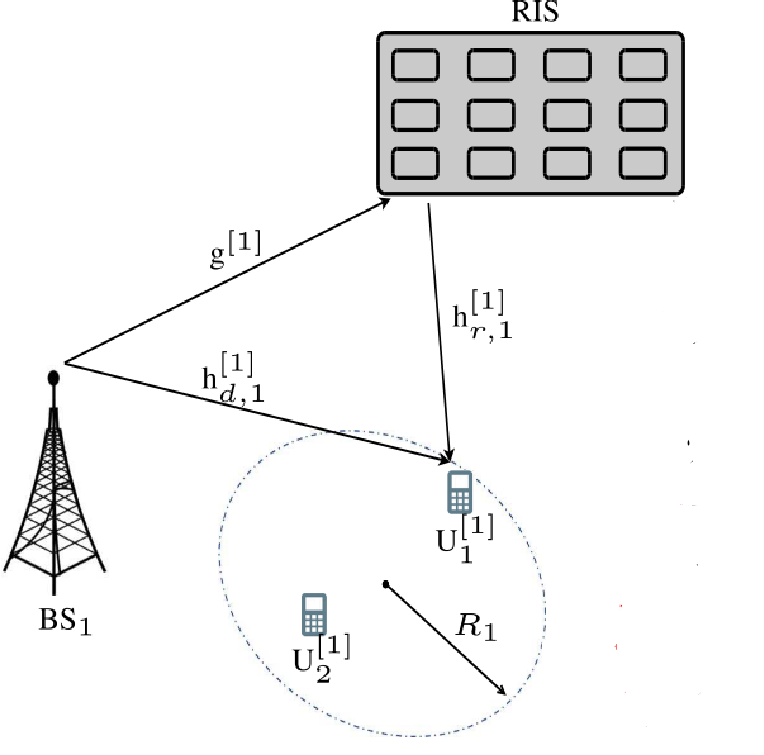


clc
close all
addpath('C:\Users\Asus irG\Documents\Github\RIS-Sharing-Scenario\modules') % You need to change the address in case you run it on your computer

% Parameters
N1 = 6;                  % Number of users
N_i = 32;                % Number of IRS elements
discrete = false;
N_bits = 3;
N_iter = 20;             % Number of iterations
P_T = (10^(40/10)) * 1e-3;   % BS power (W)
R = 10;                  % Radius
[x0, y0, z0] = deal(30, 20, 0);     % User area center
[x1, y1, z1] = deal(0, 0, 10);   % BS1 location
[x_i, y_i, z_i] = deal(25 * sqrt(2), 25 * sqrt(2), 10);   % IRS location
M_t = 1;                 % Number of transmitter antennas
M_r = 1;                 % Number of receiver antennas
alpha_d = 3.6;
alpha_r = 2;
noise_power = (10^(-114/10));   % Noise power (dBm/Hz)
interference = 0;
epsilon = 0.01;
SV = 10;
MAC = 'NOMA';


%% users location
t = 2 * pi * rand(N1 , 1) ;
r  =  R * sqrt(rand(N1 , 1)) ;
x  =  x0 + r.* cos(t) ;
y  =  y0 + r.* sin(t) ;
z = 1.5 * ones(N1 , 1) ;

## Rate vs No. RIS elements

% Initialize variables
final_Lband = zeros(SV, 2);
final_Uband = zeros(SV, 2);
final_rate = zeros(SV, 2);
random_final_rate = zeros(SV, 1);
tic
start = 10;
step = 5;
m = repmat('.', 1, SV);

% Main loop
for N = start:step:start + (SV - 1) * step
    i = (N - start) / step + 1;
    m(i) = '|';
    disp(m)
    for k = 1:N_iter
        % Generate random user locations
        t = 2 * pi * rand(N1, 1);
        r = R * sqrt(rand(N1, 1));
        x = x0 + r .* cos(t);
        y = y0 + r .* sin(t);
        
        % Calculate channel gains
        [h_d, G, h_r] = ChannelGain(M_t, M_r, N1, N, x, y, z, x1, y1, z1, ...
            x_i, y_i, z_i, alpha_d, alpha_r);
        
        % Max-Min Channel Gain
        [exact_rate, Z_cvx1] = Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
            N_bits, discrete, MAC);
        Theta = diag(Z_cvx1);
        channel_gain = sort(abs(h_d + h_r' * Theta * G));
        final_rate(i, 1) = final_rate(i, 1) + exact_rate;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2 / noise_power) / N1;
        final_Lband(i, 1) = final_Lband(i, 1) + rate_lower_bound;
        rate_upper_bound = log2(1 + P_T * channel_gain(end)^2 / noise_power) / N1;
        final_Uband(i, 1) = final_Uband(i, 1) + rate_upper_bound;
        
        % Max-Max Channel Gain
        [~, index] = max(abs(h_r') * abs(G) + abs(h_d));
        for n = 1:N
            Theta(n, n) = exp(1j * angle(h_d(index, 1)) - 1j * angle(h_r(n, index)' * G(n)));
        end
        channel_gain = sort(abs(h_d + h_r' * Theta * G));
        [exact_rate, ~] = SISONoma(epsilon, channel_gain.^2 * P_T / noise_power);
        final_rate(i, 2) = final_rate(i, 2) + exact_rate;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2 / noise_power) / N1;
        final_Lband(i, 2) = final_Lband(i, 2) + rate_lower_bound;
        rate_upper_bound = log2(1 + P_T * channel_gain(end)^2 / noise_power) / N1;
        final_Uband(i, 2) = final_Uband(i, 2) + rate_upper_bound;
        
        % Random theta
        rand_theta = exp(1j * 2 * pi * rand(N, 1));
        channel_gain = abs(h_d + h_r' * diag(rand_theta) * G);
        channel_gain = sort(abs(channel_gain));
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2 / noise_power) / N1;
        random_final_rate(i) = random_final_rate(i) + rate_lower_bound;
    end
end

|.........
||........
|||.......
||||......
|||||.....
||||||....
|||||||...
||||||||..
|||||||||.
||||||||||


toc

Elapsed time is 1.478467 seconds.



% Normalize variables
final_rate = final_rate / N_iter;
final_Lband = final_Lband / N_iter;
final_Uband = final_Uband / N_iter;
random_final_rate = random_final_rate / N_iter;

This MATLAB script generates a plot illustrating the rate performance of a communication system with varying numbers of Reconfigurable Intelligent Surface (RIS) elements. It calculates rates using different optimization methods, including upper and lower bounds, semidefinite relaxation, and random phase shifts for the IRS. The resulting plot provides insights into the system's rate behavior as the number of RIS elements changes, aiding in system optimization and design decisions.

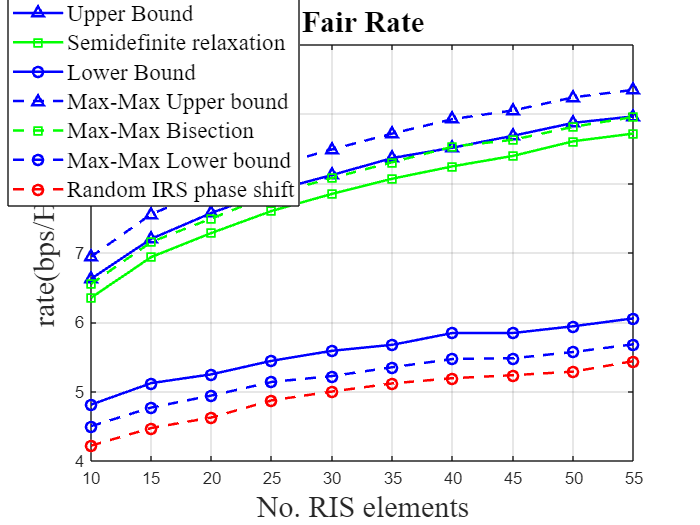

% Plot Rate
figure

% Plot Upper Bound
plot(start:step:start + (SV - 1) * step, final_Uband(:, 1), 'b-^', 'linewidth', 1.5)
hold on

% Plot Semidefinite relaxation
plot(start:step:start + (SV - 1) * step, final_rate(:, 1), 'g-s', 'linewidth', 1.5)

% Plot Lower Bound
plot(start:step:start + (SV - 1) * step, final_Lband(:, 1), 'b-o', 'linewidth', 1.5)

% Plot Max-Max Upper bound
plot(start:step:start + (SV - 1) * step, final_Uband(:, 2), 'b--^', 'linewidth', 1.5)

% Plot Max-Max Bisection
plot(start:step:start + (SV - 1) * step, final_rate(:, 2), 'g--s', 'linewidth', 1.5)

% Plot Max-Max Lower bound
plot(start:step:start + (SV - 1) * step, final_Lband(:, 2), 'b--o', 'linewidth', 1.5)

% Plot Random IRS phase shift
plot(start:step:start + (SV - 1) * step, random_final_rate, 'r--o', 'linewidth', 1.5)

% Set figure properties
set(gcf, 'color', 'w');
title('Fair Rate', 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('No. RIS elements', 'FontName', 'Times New Roman', 'FontSize', 18)
ylabel('rate(bps/Hz)', 'FontName', 'Times New Roman', 'FontSize', 18)

% Set legend
lgnd = legend('Upper Bound', 'Semidefinite relaxation', 'Lower Bound', ...
    'Max-Max Upper bound', 'Max-Max Bisection', 'Max-Max Lower bound', ...
    'Random IRS phase shift');
set(lgnd, 'FontSize', 14);
set(lgnd, 'FontName', 'Times New Roman');
% Enable grid
grid on

## Continous vs Discrete RIS Phase Shift

In this section, we use norm-2 metric to calculate the best discrete RIS configuration and compare the achievable rates fir these cases.

Questions to be answered here:

- How much does discretization decrease the performance?

- How many bits are enough?

N_bits_max = 8;
channel_gain = zeros(N1, 1);
final_rate = zeros(SV, N_bits_max + 1);
tic
start = 10;
step = 5;
m = repmat('.', 1, SV);
for N = start:step:start + (SV - 1) * step
    i = (N - start) / step + 1;
    m(i) = '|';
    disp(m)
    for k = 1:N_iter
        t = 2 * pi * rand(N1, 1);
        r = R * sqrt(rand(N1, 1));
        x = x0 + r .* cos(t);
        y = y0 + r .* sin(t);
        [h_d, G, h_r] = ChannelGain(M_t, M_r, N1, N, x, y, z, x1, y1, z1, ...
            x_i, y_i, z_i, alpha_d, alpha_r);
        [exact_rate, Z_cvx1] = Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
            N_bits, false, MAC);
        Theta = diag(Z_cvx1);
        final_rate(i, 1) = final_rate(i, 1) + exact_rate;
        for N_bits = 1:N_bits_max
            [exact_rate, Z_cvx1] = Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
                N_bits, true, MAC);
            Theta = diag(Z_cvx1);
            final_rate(i, N_bits + 1) = final_rate(i, N_bits + 1) + exact_rate;
        end
    end
end

|.........
||........
|||.......
||||......
|||||.....
||||||....
|||||||...
||||||||..
|||||||||.
||||||||||


final_rate = final_rate / N_iter;
toc

Elapsed time is 1.660537 seconds.


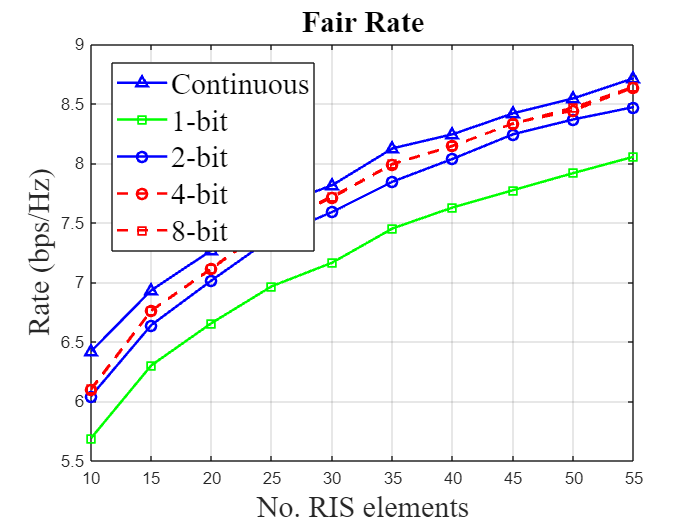

% Plot Rates
figure
plot(start:step:start + (SV - 1) * step, final_rate(:, 1), 'b-^', 'linewidth', 1.5)
hold on
plot(start:step:start + (SV - 1) * step, final_rate(:, 2), 'g-s', 'linewidth', 1.5)
plot(start:step:start + (SV - 1) * step, final_rate(:, 3), 'b-o', 'linewidth', 1.5)
plot(start:step:start + (SV - 1) * step, final_rate(:, 5), 'r--o', 'linewidth', 1.5)
plot(start:step:start + (SV - 1) * step, final_rate(:, end), 'r--s', 'linewidth', 1.5)

set(gcf, 'color', 'w');
title('Fair Rate', 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('No. RIS elements', 'FontName', 'Times New Roman', 'FontSize', 18)
ylabel('Rate (bps/Hz)', 'FontName', 'Times New Roman', 'FontSize', 18)
lgnd = legend('Continuous', '1-bit', '2-bit', '4-bit', '8-bit');
set(lgnd, 'FontSize', 18);
set(lgnd, 'FontName', 'Times New Roman');
grid on

## TDMA, FDMA, Hybrid TDMA-NOMA, and NOMA Comparison

Hybrid TDMA-NOMA can be a solution. each time slot will be allocated to a cluster consisting of $N>2$users. The IRS configuration and the power allocation problem will be solved similarly in each time slot. 

% Initialize rates
NOMA_rate = zeros(SV, 1);
TDMA_rate = zeros(SV, 1);
FDMA_rate = zeros(SV, 1);
H_TDMA_NOMA_rate = zeros(SV, 1);

tic
start = 10;
step = 5;
m = repmat('.', 1, SV);

for N = start:step:start + (SV - 1) * step
    i = (N - start) / step + 1;
    m(i) = '|';
    disp(m)
    
    for k = 1:N_iter
        t = 2 * pi * rand(N1, 1);
        r = R * sqrt(rand(N1, 1));
        x = x0 + r .* cos(t);
        y = y0 + r .* sin(t);
        
        % Channel gains
        [h_d, G, h_r] = ChannelGain(M_t, M_r, N1, N, x, y, z, x1, y1, z1, ...
                                     x_i, y_i, z_i, alpha_d, alpha_r);
                                 
        % TDMA rate
        MAC = 'TDMA';
        TDMA_rate(i) = TDMA_rate(i) + Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
                                             N_bits, discrete, MAC);
        
        % FDMA rate
        MAC = 'FDMA';
        FDMA_rate(i) = FDMA_rate(i) + Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
                                             N_bits, discrete, MAC);
        
        % NOMA rate
        MAC = 'NOMA';
        NOMA_rate(i) = NOMA_rate(i) + Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
                                             N_bits, discrete, MAC);
        
        % Hybrid TDMA NOMA rate
%         MAC = 'HTN';
        for c = 1:N1/2
            H_TDMA_NOMA_rate(i) = H_TDMA_NOMA_rate(i) + 4 / N1 * Rate(h_d(1 + (c - 1) * 2:c * 2, :), G, ...
                                                                        h_r(:, 1 + (c - 1) * 2:c * 2), 2, N, ...
                                                                        P_T, noise_power, N_bits, discrete, MAC);
        end
    end
end

|.........
||........
|||.......
||||......
|||||.....
||||||....
|||||||...
||||||||..
|||||||||.
||||||||||



% Average rates
TDMA_rate = TDMA_rate / N_iter;
FDMA_rate = FDMA_rate / N_iter;
NOMA_rate = NOMA_rate / N_iter;
H_TDMA_NOMA_rate = H_TDMA_NOMA_rate / N_iter;

toc

Elapsed time is 0.900029 seconds.


%% Plot SumRate
figure
% Draw results
plot(start:step:start + (SV - 1) * step, TDMA_rate, 'r-^', 'linewidth', 1.5)
hold on
plot(start:step:start + (SV - 1) * step, FDMA_rate, 'g-s', 'linewidth', 1.5)
plot(start:step:start + (SV - 1) * step, NOMA_rate, 'b-o', 'linewidth', 1.5)
plot(start:step:start + (SV - 1) * step, H_TDMA_NOMA_rate, 'b-s', 'linewidth', 1.5)
set(gcf, 'color', 'w');
% ylim([0 16])
title('Fair Rate', 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('No. RIS elements', 'FontName', 'Times New Roman', 'FontSize', 18)
ylabel('rate(bps/Hz)', 'FontName', 'Times New Roman', 'FontSize', 18)
lgnd = legend('TDMA', 'FDMA', 'NOMA', 'Hybrid TDMA-NOMA');
set(lgnd, 'FontSize', 18);
set(lgnd, 'FontName', 'Times New Roman');
grid on

## Alternating Optimzation (AO) for Single-BS 

This script compares four methods for optimizing the rate in a wireless communication system: 'Exhaustive Search', 'Semidefinite Relaxation', 'Alternating Optimization', and 'Random IRS Phase Shift'. It computes the upper and lower bounds of the rate for each method and evaluates their performance based on these bounds. The script iterates through different channel realizations, varying transmit power, to analyze the effectiveness of each optimization technique.

Q_e = 4;  % Number of steps of Theta for exhaustive search
N1 = 2;
N2 = 2;
N_i = 8;

final_Lband = zeros(SV, 2);
final_Uband = zeros(SV, 2);
final_rate = zeros(SV, 3); 
random_final_rate = zeros(SV, 1);
observed_rate = 0;

tic
start = 10;
step = 5;
N = N_i;
m = repmat('.', 1, SV);

for kk = 1:N_iter
    % Generate random user locations
    t = 2 * pi * rand(N1, 1);
    r = R * sqrt(rand(N1, 1));
    x = x0 + r .* cos(t);
    y = y0 + r .* sin(t);
    
    % Calculate channel gains
    [h_d, G, h_r] = ChannelGain(M_t, M_r, N1, N, x, y, z, x1, y1, z1, ...
                                 x_i, y_i, z_i, alpha_d, alpha_r);
    
    % Exhaustive Search RIS configuration
    BestRate = 0;
    Theta = zeros(N, N);
    Theta_star = zeros(N, N);
    for qq = 0:Q_e^N - 1
        Theta = diag([ones(1, N - size(dec2base(qq, Q_e), 2)) exp(1j * 2 * dec2base(qq, Q_e) * pi / Q_e)]);
        channel_gain = sort(abs(h_d + h_r' * Theta * G)).^2 * 1 / noise_power;
        q_star = (channel_gain(1) - channel_gain(2) + ...
                  sqrt((channel_gain(1) - channel_gain(2))^2 + ...
                  4 * channel_gain(1) * (channel_gain(2) + ...
                  channel_gain(1) * channel_gain(2)))) / 2 / channel_gain(1);
        channel_gain = sort(abs(h_d + h_r' * Theta * G));
        if q_star > BestRate
            BestRate = q_star;
            Theta_star = Theta;
        end
    end

    for ss = start:step:start + (SV - 1) * step
        P_T = (10^(ss / 10)) * 1e-3;
        i = (ss - start) / step + 1;
        
        % Max-Min Channel Gain
        [exact_rate, Z_cvx1] = Rate(h_d, G, h_r, N1, N, P_T, noise_power, ...
                                      N_bits, discrete, MAC);
        Theta = diag(Z_cvx1);
        channel_gain = sort(abs(h_d + h_r' * Theta * G));
        final_rate(i, 1) = final_rate(i, 1) + exact_rate;
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2 / noise_power) / N1;
        final_Lband(i, 1) = final_Lband(i, 1) + rate_lower_bound;
        rate_upper_bound = log2(1 + P_T * channel_gain(end)^2 / noise_power) / N1;
        final_Uband(i, 1) = final_Uband(i, 1) + rate_upper_bound;

        % Alternating Optimization
        phi = zeros(N, N1); 
        Q = zeros(N + 1, N + 1, N1); 
        for ii = 1:N1 
            phi(:, ii) = diag(h_r(:, ii)') * G; 
            Q(:, :, ii) = [phi(:, ii) * transpose(conj(phi(:, ii))) conj(h_d(ii)) * phi(:, ii); ...
                           h_d(ii) * transpose(conj(phi(:, ii))) 0]; 
        end
        convergence = false;
        Theta = diag(exp(1j * randn(N, 1))); 
        BestRate = 0;
        while convergence == false
            % Power Allocation Sub-problem
            [rate, b] = SISONoma(epsilon, P_T * sort(abs(h_d + h_r' * Theta * G).^2) / noise_power);
            if rate > BestRate
                BestRate = rate;
                if abs(rate - BestRate) < epsilon
                    convergence = true;
                end            
            end
            observed_rate = [observed_rate; rate];

            % RIS Configuration Sub-problem
            q_min = 1;
            q_max = 100;
            while q_max - q_min >= epsilon
                q = (q_min + q_max) / 2;

                Q = 10^13 * Q; 
                cvx_begin sdp quiet
                    variable X(N + 1, N + 1) complex hermitian;
                    maximize 0
                    subject to 
                        for k = 1:N1
                            1 + (b(k) - b(k + 1) * q) * (10^13 * abs(h_d(k))^2 + real(trace(Q(:, :, k) * X))) >= q
                        end
                        diag(X) == 1; 
                        X == hermitian_semidefinite(N + 1); 
                cvx_end
                Q = 10^(-13) * Q;
                if cvx_status(1:6) == 'Infeas'
                    q_max = q;
                else
                    q_min = q;
                    X_star = X;
                end
            end

            % Gaussian Randomization
            N_r = 1000;
            Z = X_star;
            [~, S, V] = svd(conj(Z)); 
            V_prime = V * sqrt(S); 
            z_hat = zeros(N + 1, 1); 
            achievable_q = 0;
            for g = 1:N_r
                r = sqrt(0.5) * (randn(N + 1, 1) + 1j * randn(N + 1, 1));  % r~CSCG(0,I)
                z_hat = V_prime * r; 
                z_hat = z_hat ./ z_hat(N + 1); 
                z_hat = exp(1j * angle(z_hat(1:N))); 
                if min((P_T * b(1:N1) .* abs(h_d + h_r' * diag(z_hat) * G).^2 + noise_power) ...
                       ./ (P_T * b(2:N1 + 1) .* abs(h_d + h_r' * diag(z_hat) * G).^2 + noise_power)) >= achievable_q
                    achievable_q = min((P_T * b(1:N1) .* abs(h_d + h_r' * diag(z_hat) * G).^2 + noise_power) ...
                                       ./ (P_T * b(2:N1 + 1) .* abs(h_d + h_r' * diag(z_hat) * G).^2 + noise_power));
                    z_star = z_hat;
                end
            end
            Theta = diag(z_star); 
        end

        exact_rate = BestRate;
        final_rate(i, 2) = final_rate(i, 2) + exact_rate;

        % Exhaustive Search power allocation
        channel_gain = sort(abs(h_d + h_r' * Theta_star * G)).^2 * P_T / noise_power;
        q_star = (channel_gain(1) - channel_gain(2) + ...
                  sqrt((channel_gain(1) - channel_gain(2))^2 + ...
                  4 * channel_gain(1) * (channel_gain(2) + ...
                  channel_gain(1) * channel_gain(2)))) / 2 / channel_gain(1);
        exact_rate = log2(q_star);
        final_rate(i, 3) = final_rate(i, 3) + exact_rate;

        % Random theta
        rand_theta = exp(1j * 2 * pi * rand(N, 1)); 
        channel_gain = abs(h_d + h_r' * diag(rand_theta) * G); 
        channel_gain = sort(abs(channel_gain)); 
        rate_lower_bound = log2(1 + P_T * channel_gain(1)^2 / noise_power) / N1;
        random_final_rate(i) = random_final_rate(i) + rate_lower_bound;
    end
end
toc

final_Lband = final_Lband/N_iter ;
final_Uband = final_Uband/N_iter ;
final_rate = final_rate/N_iter ;
random_final_rate = random_final_rate/N_iter ;

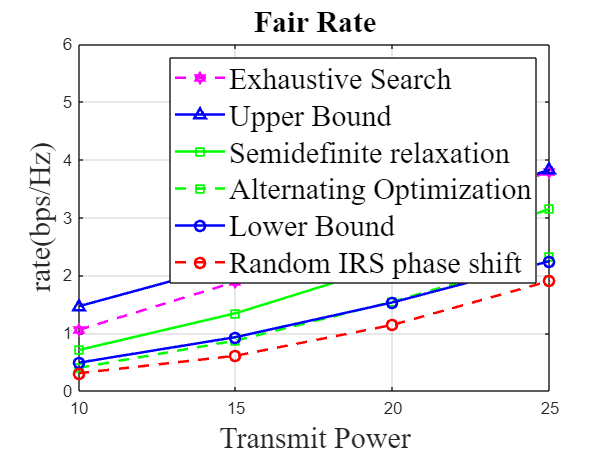

figure

%% Draw results
plot(start : step : start + (SV - 1) * step , final_rate(: , 3) ,  'm--hexagram' , 'linewidth' , 1.5)
hold on
plot(start : step : start + (SV - 1) * step , final_Uband(: , 1) ,  'b-^' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , final_rate(: , 1) ,  'g-s' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , final_rate(: , 2) ,  'g--s' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , final_Lband(: , 1) ,  'b-o' , 'linewidth' , 1.5)
plot(start : step : start + (SV - 1) * step , random_final_rate ,  'r--o' , 'linewidth' , 1.5)
lgnd = legend('Exhaustive Search', 'Upper Bound', 'Semidefinite Relaxation', 'Alternating Optimization', 'Lower Bound', 'Random IRS Phase Shift');
set(gcf , 'color' , 'w');
ylim([0 6])
title('Fair Rate', 'FontName', 'Times New Roman', 'FontSize', 18)
xlabel('Transmit Power', 'FontName', 'Times New Roman', 'FontSize', 18)
ylabel('Rate (bps/Hz)', 'FontName', 'Times New Roman', 'FontSize', 18)
set(lgnd, 'FontSize', 18);
set(lgnd, 'FontName', 'Times New Roman');
grid on
